# Option C - Compare Edge Detectors

Digital Signal Processing - Individual Image Processing Experiment

Question: How do Sobel (with sigma=1 pre-smoothing), Canny sigma=1, and Canny sigma=3 respond to clean and Gaussian-noisy cameraman.tif?

Image: cameraman.tif (MATLAB Image Processing Toolbox sample) Noise: rng(42); imnoise(I,'gaussian',0,0.01) All edge thresholds are automatic (default); other settings unchanged.

After running, review the six maps, counts, and zoomed region. Add your own visually verified observation before submission.

close all; clear; clc;

## 1. Load the reference image and add Gaussian noise

imageName = 'cameraman.tif';
I = im2double(imread(imageName));
if ndims(I) ~= 2
    error('Expected grayscale cameraman.tif.');
end

rng(42);
In = imnoise(I,'gaussian',0,0.01);

if ~exist('results','dir')
    mkdir('results');
end

fprintf('Option C: Edge Detector Comparison\n');

Option C: Edge Detector Comparison


fprintf('MATLAB version: %s\n', version);

MATLAB version: 26.2.0.3468271 (R2026b) Update 2


fprintf('Image: %s (%d x %d pixels)\n', imageName, size(I,1), size(I,2));

Image: cameraman.tif (256 x 256 pixels)


fprintf('Noise: Gaussian, mean=0, variance=0.01, rng(42)\n');

Noise: Gaussian, mean=0, variance=0.01, rng(42)


## 2. Apply the three specified edge detectors

Sobel uses the image pre-smoothed by imgaussfilt(...,1). For Canny, [] requests the default automatic thresholds. The sigma argument is 1 or 3, as requested.

sobelClean = edge(imgaussfilt(I,1), 'Sobel');
sobelNoisy = edge(imgaussfilt(In,1), 'Sobel');

canny1Clean = edge(I, 'Canny', [], 1);
canny1Noisy = edge(In, 'Canny', [], 1);

canny3Clean = edge(I, 'Canny', [], 3);
canny3Noisy = edge(In, 'Canny', [], 3);

## 3. Show all six edge maps in a single figure

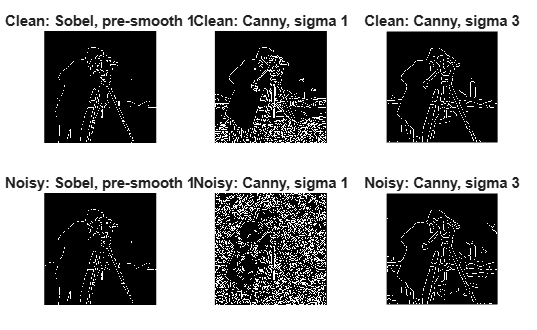

figure1 = figure('Name','Option C - Six edge maps','Color','w', ...
    'Position',[100 100 1120 690]);
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');

nexttile; imshow(sobelClean); title('Clean: Sobel, pre-smooth 1');
nexttile; imshow(canny1Clean); title('Clean: Canny, sigma 1');
nexttile; imshow(canny3Clean); title('Clean: Canny, sigma 3');
nexttile; imshow(sobelNoisy); title('Noisy: Sobel, pre-smooth 1');
nexttile; imshow(canny1Noisy); title('Noisy: Canny, sigma 1');
nexttile; imshow(canny3Noisy); title('Noisy: Canny, sigma 3');

exportgraphics(figure1,fullfile('results','01_six_edge_maps.png'), 'Resolution',170);

## 4. Count edge pixels and save the comparison table

method = {'Sobel (pre-smooth sigma 1)'; 'Canny (sigma 1)'; 'Canny (sigma 3)'};
cleanCount = [nnz(sobelClean); nnz(canny1Clean); nnz(canny3Clean)];
noisyCount = [nnz(sobelNoisy); nnz(canny1Noisy); nnz(canny3Noisy)];
deltaCount = noisyCount - cleanCount;

T = table(method,cleanCount,noisyCount,deltaCount, ...
    'VariableNames',{'Method','Clean_edge_pixels','Noisy_edge_pixels','Noisy_minus_clean'});
disp(T);

                Method                Clean_edge_pixels    Noisy_edge_pixels    Noisy_minus_clean
    ______________________________    _________________    _________________    _________________

    {'Sobel (pre-smooth sigma 1)'}          2099                  2024                  -75      
    {'Canny (sigma 1)'           }          7816                 18122                10306      
    {'Canny (sigma 3)'           }          2780                  3185                  405      



writetable(T, fullfile('results','edge_pixel_counts.csv'));

## 5. Inspect one fixed region for lost or spurious edges

This lower-right region is a suggested inspection area. Look at the image yourself and describe ONE specific edge that is lost or invented. The zoom does not prove which detected edges are actually correct.

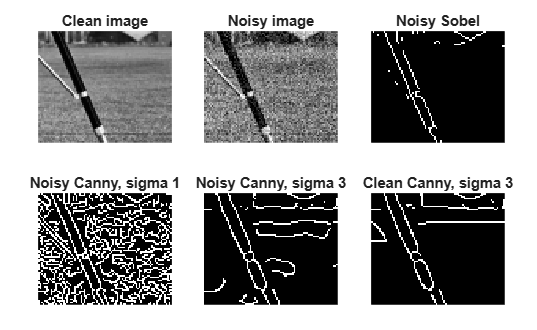

nRows = size(I,1); nCols = size(I,2);
rows = max(1,round(0.65*nRows)) : min(nRows,round(0.92*nRows));
cols = max(1,round(0.60*nCols)) : min(nCols,round(0.93*nCols));

figure2 = figure('Name','Option C - Selected region','Color','w', ...
    'Position',[120 120 1120 690]);
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
nexttile; imshow(I(rows,cols),[]); title('Clean image');
nexttile; imshow(In(rows,cols),[]); title('Noisy image');
nexttile; imshow(sobelNoisy(rows,cols)); title('Noisy Sobel');
nexttile; imshow(canny1Noisy(rows,cols)); title('Noisy Canny, sigma 1');
nexttile; imshow(canny3Noisy(rows,cols)); title('Noisy Canny, sigma 3');
nexttile; imshow(canny3Clean(rows,cols)); title('Clean Canny, sigma 3');
exportgraphics(figure2,fullfile('results','02_selected_region.png'), 'Resolution',170);

## 6. Discussion to complete after checking the plots

Effect of smoothing and sigma: Larger Gaussian sigma suppresses fine/high-frequency variation before Canny edge detection, but it can also remove thin or weak real edges.

One observed region: [After running, name the edge/feature visible or missing in the zoom.]

Main conclusion: [After running, say which detector you prefer and why based on your maps.]

Limitation: Edge-pixel counts measure how many pixels were marked, NOT whether those marked pixels correspond to true edges (no ground-truth map).

fprintf('\nSaved results/01_six_edge_maps.png\n');


Saved results/01_six_edge_maps.png


fprintf('Saved results/02_selected_region.png\n');

Saved results/02_selected_region.png


fprintf('Saved results/edge_pixel_counts.csv\n');

Saved results/edge_pixel_counts.csv
